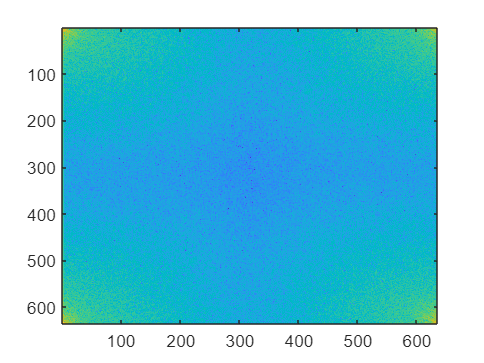

dog = imread('squaredog.jpg');
imc = imread('squarecat.jpg');

Rd = dog(:,:,1);
Gd = dog(:,:,2);
Bd = dog(:,:,3);

Rc = imc(:,:,1);
Gc = imc(:,:,2);
Bc = imc(:,:,3);



D = fft2(Rd);
C = fft2(Rc);
magd = abs(D);
phsd = angle(D);
magc = abs(C);
phsc = angle(C);

phsc(phsc > -1) = phsd(phsc > -1);

I = magd.*exp(1i.*phsc);
R = uint8(abs(ifft2(I)));

D = fft2(Gd);
C = fft2(Gc);
magd = abs(D);
phsd = angle(D);
magc = abs(C);
phsc = angle(C);

phsc(phsc > -1) = phsd(phsc > -1);

I = magd.*exp(1i.*phsc);
G = uint8(abs(ifft2(I)));


D = fft2(Bd);
C = fft2(Bc);
magd = abs(D);
phsd = angle(D);
magc = abs(C);
phsc = angle(C);

phsc(phsc > -1) = phsd(phsc > -1);

I = magd.*exp(1i.*phsc);
B = uint8(abs(ifft2(I)));


imagesc(log(abs(I)));

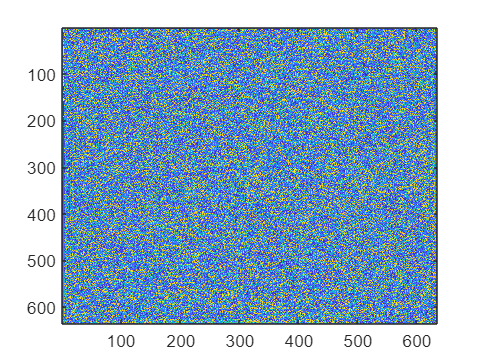

imagesc(angle(I));

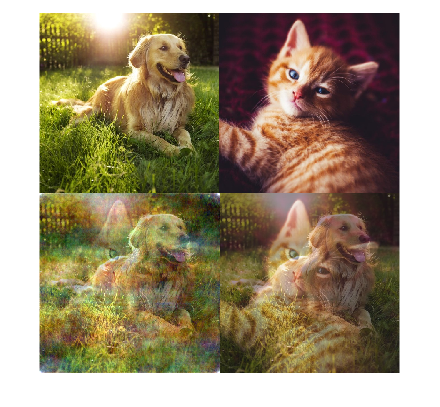


outImg = cat(3,R,G,B);
%outImg = uint8(abs(ifft2(outImg)));

toSave = montage({dog,imc,outImg,imfuse(dog,imc,'blend')});